clear all, close all, clc
tic

**RVEC - Rail Vehicle Energy Calculator **

**Train, terrain, driving style etc**

% Terrain & Track data upload
% from the Excel input file Energy_calculation containing multiple sheets

input_data_terrain = readmatrix('Energy_calculation - Test.xlsx','sheet','Master');

input_data_train = readmatrix('Energy_calculation - Test.xlsx','sheet','train_data');

% Terrain & Track data extraction

distance = input_data_terrain(:,2); % km; Array of break points at the respective distance

section_distance = diff(distance); % length of each section

max_speed_track = (5/18)*input_data_terrain(:,3); % m/s ... In excel its in km/h

height = input_data_terrain(:,4); % Elevation in meters

gradient = input_data_terrain(:,10); % Gradient per mil

Rcurvature = input_data_terrain(:,5); % Curve Radius in meters

curveType = input_data_terrain(:,9); % [0 means circular curve; 1 means clothoid curve]

halt = input_data_terrain(:,8); % in seconds; train stopping time in seconds

travel_time = input_data_terrain(:,14); % travel time data

% Traction or Brake based on defined driving pattern

mechBrake_percent = input_data_terrain(:,6); % in percentage; defined as per driving style

regenBrake_percent = input_data_terrain(:,7); % in percentage; defined as per driving style

traction_percent = input_data_terrain(:,11); % in percentage; defined as per driving style

coasting = input_data_terrain(:,13); % binary, 0 means coasting Off

max_mechBrake_percent = input_data_train(36,2); % in percentage; defined as per driving style

max_regenBrake_percent = input_data_train(38,2); % in percentage; defined as per driving style

% if target speed while braking is not achieveable as per current braking driving style,
% braking force is incremented in increment steps until a value defined by max_mechBrake_percent
% these increments are taken from the Excel sheet train_data and can be changed in excel

mechBrake_increment = input_data_train(40,2); % in percentage;

regenBrake_increment = input_data_train(41,2); % in percentage

speed_tractionOff = (5/18)*input_data_train(37,2); % cut off speed [m/s], Regeneration is Zero below this speed


**Train data**

massVehicle= 1000*input_data_train(1,2); % kg (without passenger & cargo load)

kappa_v = input_data_train(2,2); % Relative Mass Addition in percentage, taking into account rotational inertia

adhesionMass = 1000*input_data_train(3,2); % kg; mass on all powered axles

brakedMass = 1000*input_data_train(4,2); % kg; mass on all braked axles, can be given different values to be checked

load = 1000*input_data_train(5,2); % kg; mass as passanger+cargo load

acceleration_maxComfort =input_data_train(6,2); % m/s2 as per EN or other standard

retardation_maxComfort = input_data_train(7,2); % m/s2 as per EN or other standard

wheel_diameter = 0.001*input_data_train(8,2); % m; train wheel diameter

equivalentmassVehicle = massVehicle*(1+kappa_v) + load; % kg; On Considering rotational inertia

slipControl = input_data_train(9,2); % Slip control [0 means no and 1 yes]

% despite slip control, there is always a slip between Wheel and track, so
% wheel generally rotates a little faster

s = input_data_train(10,2); % Slip value ; constant value as of now, to be changed later on, modify the slip while braking

gearRatio =  input_data_train(22,2); % Motor / Axle gear

gearEfficiency =  input_data_train(23,2); % constant

aux_power = input_data_train(28,2); % constant auxiliary power as of now [kW]

no_inductMotor = input_data_train(25,2); % number of induction motors

motor_ratedPower = input_data_train(26,2); % max motor rated power [kW]

Rated_RPM = input_data_train(27,2); % Rated RPM of motor

alpha_traction = input_data_train(43,2); % adhesion utilization limit while traction

alpha_brake = input_data_train(44,2); % adhesion utilization limit while braking

inverterRatedPower = input_data_train(48,2); % Inverter rated Input power

simulation_type = input_data_train(46,2); % Inverter rated Input power

% Input data of Efficiency maps from excel sheets

motor_efficiency = readmatrix('Energy_calculation - Test.xlsx','sheet','motor_efficiency');

inverter_efficiency = readmatrix('Energy_calculation - Test.xlsx','sheet','inverter_efficiency');

absorptionCkt_efficiency = input_data_train(32,2); % Constant percentage

lineConverter_efficiency = readmatrix('Energy_calculation - Test.xlsx','sheet','lineconverter_efficiency');

transformer_efficiency = readmatrix('Energy_calculation - Test.xlsx','sheet','lineconverter_efficiency');

% Input data from excel sheet, traction_curve

input_data_traction = readmatrix('Energy_calculation - Test.xlsx','sheet','traction_curve');

velocity_tractionCurve = (5/18)*input_data_traction(:,1); % m/s ... In excel its in km/h

tractionForce_tractionCurve = 1000*input_data_traction(:,2); % N ... In excel its in kN

peak_tractionForce_tractionCurve = 1000*input_data_traction(:,5); % N ... In excel its in kN

if slipControl == 1 % If slip control is available and selected in Train_data excel sheet

    tractionForce_adhesion_tractionCurve = adhesionMass*input_data_traction(:,3)*9.81; % N   % Slip control leads to different friction coefficient i.e. in Column C in Excel sheet traction_curve

else

    tractionForce_adhesion_tractionCurve = adhesionMass*input_data_traction(:,4)*9.81; % N   % Without slip control, friction coefficient is different and is selected from Column D in the Excel sheet traction_curve

end

% Input data from excel sheet, brake_curve

input_data_brake = readmatrix('Energy_calculation - Test.xlsx','sheet','brake_curve');

velocity_brakeCurve = (5/18)*input_data_brake(:,1); % m/s ... In excel its in km/h

mechbrakeForce_brakeCurve = 1000*input_data_brake(:,2); % N

regenbrakeForce_tractionCurve = 1000*input_data_brake(:,5); % N check if some factor multiplication is required

if slipControl == 1

    Brake_adhesion_tractionCurve = brakedMass*input_data_brake(:,3)*9.81; % in Newtons

else

    Brake_adhesion_tractionCurve = brakedMass*input_data_brake(:,4)*9.81; % in Newtons

end

% Rolling Resistance is defined by 'A+bv+Cv^2' where A,B,C are train specific coefficients

A = input_data_train(13,2); % [N] Rolling resistance coefficient

B = input_data_train(14,2); % [Ns/m] 1st coefficient for air resistance

C = input_data_train(15,2); % [Ns^2/m^2] 2nd coefficient for air resistance

% Curvature definition (a*M_veh)/(R-b)

a = input_data_train(18,2); % 'a' coefficient in Curving Resistance

b = input_data_train(19,2); % 'b' coefficient in Curving Resistance

**Calculations**

% delta_X = inputdlg('Enter dx value:','Delta x', [1 10]);
%
% dx = str2num(delta_X{1}); % distance step size(in meters), Can't be too high like 100 m that error in calculation)

dx = 10;
k = 1; % counter for the whole curve from Beginning 1st section till last section

max_speed = [max_speed_track(1:end)].*(halt==0); % to get target speeds in the section after taking in account the zero velocity at stations


% Pre-defining variables to allocate memory:
% 'curve' is for the whole journey
% 'space' is for the current section which is dynamic and changes with each section based on its length

velocity_curve = zeros(1,(1 + 1000*distance(end)/dx) + nnz(halt));

time_curve = zeros(1,length(velocity_curve));

wheelTorque_curve = zeros(1,length(velocity_curve));

acc_curve = zeros(1,length(velocity_curve));

distance_curve = dx*ones(1,length(velocity_curve));

adhesionUtilization_curve = zeros(1,length(velocity_curve));

distance_space = 0:dx:(1000*(distance(2) - distance(1))); % in meters

velocity_space = zeros(1,length(distance_space)); % calculated in m/s

gradientResistance = zeros(length(distance),1);

curvatureResistance = zeros(length(distance),1);

% Pre calculations for Gradient and Curving resistance in [N], Its fixed for each respective section due to Terrain

for i = 1:length(distance)

    if and(nnz(height) > 0,i<length(distance))           %% Gradient resistance if 'Altitude' is given

        gradientResistance(i) = (massVehicle+load)*9.81*0.001*(height(i+1)-height(i))/(distance(i+1)-distance(i));

    elseif nnz(gradient) > 0                             %% Gradient resistance if 'per mil' is given

        gradientResistance(i) = (massVehicle+load)*9.81*0.001*gradient(i);

    end

    if curveType(i) == 0                                 %% Curving resistance if 'Circular' curve

        curvatureResistance(i) = (a*(massVehicle+load)/(Rcurvature(i)-b))*(fix(Rcurvature(i)/1)/Rcurvature(i));

    elseif curveType(i) == 1                             %% Curving resistance if 'Clothoid' curve

        curvatureResistance(i) = (-a*(massVehicle+load)*Rcurvature(i)*...
            ((b^-2)*(log(1-b/Rcurvature(i))) + ((b*Rcurvature(i))^-1)))*(fix(Rcurvature(i)/1)/Rcurvature(i));

    end
end

% Caution
fprintf('Caution: %i non-zero cells in height Column D & %i non-zero cells in gradient column J. Either one has to be zero, otherwise please update either column D or J in excel' , nnz(height),nnz(gradient))

% Main calculations



insufficientSectionbrake_caution = 0; % Its used as a flag in intermediate step if target velocity at the end of section is not achieved

brakeIncrement_caution = 0;

brake_limit_no = 0; % to check in how many distance steps brake is limited due to adhesion

traction_limit_no = 0; % to check in how many distance steps traction is limited due to adhesion

terminating_coasting = 0; % used to get out of coasting loop

coasting_count = 0; % used to count coasting steps(distance) as defined in the Coasting function

allOut = 0;

kSpace = zeros(1,length(distance));

kSpace(1) = 1;

p = ones(1,length(distance));

eligibleCoasting = [];

for i=1:length(halt)-1

    if halt(i+1) > 1

        eligibleCoasting = [eligibleCoasting;i];

        if gradientResistance(i) > 0
            eligibleCoasting(end) = []

        end

    end

end

% april
coast2brake = 1;

tractionPercent_cruising = zeros(1,length(distance));

if simulation_type < 1.1

    mode = 0; % 0 = all out, 1 = meeting time table, 2 = max coasting % change into an excel input

elseif simulation_type < 2.1

    mode = 0;

    traction_percent(eligibleCoasting) = 0;

elseif simulation_type < 3.1

    mode = 0;

    traction_percent(eligibleCoasting) = 0;

    coast2brake = 0;

elseif simulation_type < 4.1

    mode = 1;

elseif simulation_type < 5.1

    mode = 1;

    traction_percent(eligibleCoasting) = 0;

end


% Main loop

i = 1; % Index for section break point

ranking_criterion = 5; % 1 = reduced product of V and section distance, 2 peak shaving



while i <= length(distance) - 1                                 %% minus 1 as the last distance point is the final terminal stop

    deltaT_space = zeros(1,length(distance_space));             %% Space : local space within section to allocate the memory, overwritten with the calculated values

    torqueWheel_space = zeros(1,length(distance_space));

    a_x_space = zeros(1,length(distance_space));

    adhesionUtilization_space = zeros(1,length(distance_space));

    if  p(i)*max_speed_track(i)  >= velocity_space(end)              %% Acceleration is required at the beginning

        j = 1;                                                  % Counter for distance space

        ifAcc = 1; %toggle switch for detecting the accceleration mode i.e. 1

        while and(and((velocity_space(j) <= p(i)*max_speed_track(i)),(j<length(distance_space))),terminating_coasting < 1)  % Enter into a track: Until current velocity is less than target velocity at the beginning of the track OR track ends OR termination is required for coasting if it was On for the section

            runningResistance = (A + B*velocity_space(j) + C*velocity_space(j)^2); % Running Resistance as per A,B, & C Coefficients

            traction_at_wheel = min([traction_percent(i)*(interp1(velocity_tractionCurve,tractionForce_tractionCurve,velocity_space(j))),...
                interp1(velocity_tractionCurve,tractionForce_adhesion_tractionCurve,velocity_space(j))]); % Traction force from the Traction curve by interpolation at the current velocity and also according to the driving pattern percentage from the excel sheet 'terrain'. And compare this traction force with available adhesion as per friction.

            a_x = (traction_at_wheel - gradientResistance(i) - curvatureResistance(i) - runningResistance)/equivalentmassVehicle; % Calculate acceleration from the force balance

            adhesionUtilization_T = (equivalentmassVehicle*a_x + gradientResistance(i) + curvatureResistance(i) + runningResistance)/(adhesionMass*9.81); % Adhesion utilization calculation

            if and(a_x < 0,and(traction_percent(i) > 0.01,max_speed(i) > 5/3.6)) % acceleration can be negative due to low traction at higher speed; so target section velocity has to be lowered.
                % and(a_x < 0,and(traction_percent(i) > 0.01,max_speed(i) > 5/3.6)) to get out of this while loop for acceleration and to not enter the next loop for deceleration

                traction_percent(i) = 1.00;

                insufficientSectionbrake_caution = i;

                %j = length(distance_space) + 1;

                warning('Negative acceleration %f m/s2 for traction = %f. Check the gradient, traction curve etc in case of error',a_x,traction_percent(i))

                velocity_space(end) = p(i+1)*max_speed(i+1);

                break;

            elseif and(a_x < 0,and(traction_percent(i) > 0.99,max_speed(i) < 10/3.6))  % Target speed is lowered till < 10 kmph and even with 100 % traction, still its not sufficient to get + acceleration.  Error Message : Negative acceleration and traction is not sufficient to accelerate in Non-coasting mode

                error('Error: Negative acceleration(%f m/s^2) is detected when acceleration is needed; Sufficient traction is not available, check traction curve or use a better Tractive Motor or lower the current target speed to see if traction is sufficient at low speed',a_x)

            elseif and(a_x < 0,traction_percent(i) < 0.01)

                traction_percent(i) = 1.00;

                coasting(i) = 1; % added on 16th April

                j = 1; % To restart the while loop calculation with 100% traction force

            elseif and(traction_percent(i) < 1,and(a_x > 0,a_x < 1e-4))

                traction_percent(i) = 1.00;

                j = 1;

            elseif and(a_x > 0,a_x < 1e-4) % if acceleration is + but very low, so to exit acceleration and get into cruise mode

                traction_percent(i) = 1.00;

                insufficientSectionbrake_caution = i;

                max_speed(i) = velocity_space(j)/0.955; % to target the speed at which acceleration starts to become very low (1e-4)

                %j = length(distance_space) + 1;

                velocity_space(end) = p(i+1)*max_speed(i+1);

                break;

            else % this implied a_x is +

                if adhesionUtilization_T < alpha_traction % comparing adhesion utilization with the alpha traction limit

                    adhesionUtilization_space(j) = adhesionUtilization_T;

                else % Limiting acceleration and traction force due to higher adhesion utilization

                    fprintf('Information: Higher adhesion utilization (%f) than available limit(%f) shall be there if current traction(%f N) is used resulting in acceleration of (%f m/s^2).' , adhesionUtilization_T,alpha_traction,round(0.001*traction_at_wheel),a_x)

                    adhesionUtilization_T = alpha_traction;

                    adhesionUtilization_space(j) = adhesionUtilization_T;

                    a_x = (adhesionMass*9.81*alpha_traction - (gradientResistance(i) + curvatureResistance(i) + runningResistance))/equivalentmassVehicle;

                    traction_at_wheel = a_x*equivalentmassVehicle + (gradientResistance(i) + curvatureResistance(i) + runningResistance);

                    traction_limit_no = traction_limit_no + 1; % counter to activate the breach of traction limit to to higher adhesion utilization

                    fprintf('So, traction is limited to (%f kN) to get an acceleration of (%f m/s^2) at the adhesion utilization of (%f)',round(0.001*traction_at_wheel),a_x,adhesionUtilization_T)

                    if a_x <= 0
                        % to find for previous velocity when acceleration
                        % was + as now at current larger velocity, running
                        % resistance is bigger and traction force is lesser
                        findpositiveAcc = find((adhesionMass*9.81*alpha_traction - (gradientResistance(i) + curvatureResistance(i) + A + B.*velocity_space(1:j-1) + C.*velocity_space(1:j-1).^2))./equivalentmassVehicle > 0);

                        if max(findpositiveAcc) > 0

                            j = max(findpositiveAcc)

                            traction_percent(i) = 1.00;

                            insufficientSectionbrake_caution = i;

                            max_speed(i) = velocity_space(j)/0.955; % to target the cruising speed at which acceleration starts to become very low (1e-4)

                            velocity_space(end) = p(i+1)*max_speed(i+1);

                        else

                            error("Calculation can't proceed further : Current Adhesion utilization > Adhesion utilization available at current acceleration. If traction is limited to meet the Adhesion utilization limit (%f), Acceleration(%f m/s^2) is negative and hence train can't accelerate. Check adhesion mass or adhesion limit(Alpha) for traction.",alpha_traction,a_x)

                        end

                    elseif and(a_x > 0,a_x < 1e-4) % (1e-4 can be increased or decreased also)

                        traction_percent(i) = 1.00;

                        insufficientSectionbrake_caution = i;

                        max_speed(i) = velocity_space(j)/0.955; % to target the cruising speed at which acceleration starts to become very low (1e-4)

                        %j = length(distance_space) + 1;

                        velocity_space(end) = p(i+1)*max_speed(i+1);

                        break;

                    end

                end

                if a_x > acceleration_maxComfort         % Lowering traction force if acceleration is more than maximum comfort limit {{{{RE-TEST THIS LOOP FOR EXTREME SLOPE DOWNHILL

                    traction_at_wheel = equivalentmassVehicle*acceleration_maxComfort + gradientResistance(i) + curvatureResistance(i) + runningResistance;

                    if traction_at_wheel < 0 % Caution: acceleration limit is breached and needs braking force to stop it now

                        warning('Accelerating due to negative gradient, braking force of %f [kN] is required',-traction_at_wheel/1000)

                    end

                    a_x = acceleration_maxComfort;

                    traction_limit_no = traction_limit_no + 1; % counter to activate the breach of traction limit to to higher adhesion utilization

                end

                if (velocity_space(j)^2 + 2*dx*a_x) > 0 % Velocity at the next distance step

                    velocity_space(j+1) = sqrt(velocity_space(j)^2 + 2*dx*a_x);

                else

                    velocity_space(j+1) = 0; % If conditional statement is negative due to retardation. (Applicable for coasting)

                end

                deltaT_space(j) = (velocity_space(j+1) - velocity_space(j))/a_x; % calculate the travel time for distance step

                torqueWheel_space(j) = 0.5*wheel_diameter*traction_at_wheel;     % calculate torque over distance step

                a_x_space(j) = a_x; % update the acceleration space field with the acceleration value

                %j = j+1;         % commented for time being, trying something


                % Coasting calculations if coasting is available in the section

                if traction_percent(i) < 0.01 % or(traction_percent(i) < 0.01,coasting(i) > 0.01) % Coasting is ON if traction_percent is zero for the section

                    [~,coasting_count,~] = f_coast(dx,equivalentmassVehicle,A,B,C,velocity_space(j),gradientResistance(i),curvatureResistance(i),p(i+1)*max_speed(i+1)); % Use coasting fucntion 'f_coast' to find the coasting distance steps for reaching end of section speed

                    if coasting_count < length(distance_space) % if coasting results in train reaching the targeted end of section speed somewhere in the section but not the end, then Coasting has to be accompanied with traction in initial distances of the section

                        j = 1; % Index reset for restarting the section calculation, now with both traction and coasting active in the section

                        velocity_space = velocity_curve(k).*ones(1,length(distance_space)); % Reset the velocity for the restarting the calculations

                        traction_percent(i) = 1; % To activate Traction

                        coasting(i) = 1;        % To also activate Coasting

                    else

                        j = j + 1;  % If Coasting distance is bigger than the section distance, then braking has to be applied in the next section of the script for deceleration

                    end

                elseif coasting(i) > 0.01  % Coasting active along with traction.

                    [vCoast_field,coasting_count,a_x_Coastfield] = f_coast(dx,equivalentmassVehicle,A,B,C,velocity_space(j+1),gradientResistance(i),curvatureResistance(i),p(i+1)*max_speed(i+1));

                    if (j + 1 + coasting_count) <= length(distance_space) % April equal to sign added

                        j = j + 1;


                    else

                        terminating_coasting = 1 % if distance is small, so that full acceleration is not possible, acceleration and coasting loop has to be terminated early %{{{{ TRIAL RUN TO BE CHECKED FOR A SMALLER SECTION)

                        terminating_At = i

                        fprintf('Caution: Distance is small that full acceleration to top speed is not possible and the followed by crusing + coasting + braking')

                        j = j + (j + 1 < length(distance_space)) % april

                    end

                else % if Coasting is OFF

                    j = j+1;

                end

            end

        end

        if and(j < length(distance_space),insufficientSectionbrake_caution < i)      %% Cruising i.e. constant speed travel for the rest of section

            if (runningResistance + curvatureResistance(i) + gradientResistance(i)) < 0

                brake_avl_adhesion = interp1(velocity_brakeCurve,Brake_adhesion_tractionCurve,velocity_space(j)); % Interpolation of braking force as per velocity and friction force

                brake_applied_M = mechBrake_percent(i).*(interp1(velocity_brakeCurve,mechbrakeForce_brakeCurve,velocity_space(j))); % Interpolating Mechanical Brake

                brake_applied_R = regenBrake_percent(i).*(interp1(velocity_brakeCurve,regenbrakeForce_tractionCurve,velocity_space(j))); % Interpolating Regenerative Brake

                brake_applied = brake_applied_M + brake_applied_R; % Net brake Mechanical + Regenerative brake as per driving pattern or requirement of braking force

                brake_at_wheel = min([brake_avl_adhesion,brake_applied]); % Comparing applied brake with Maximum available as per adhesion and selecting the smaller

                % somewhere brake limitation has to be inserted too due to
                % adhesion_brake


                if mechBrake_percent(i) < 0.01

                    adh_B = abs(equivalentmassVehicle*(0) - (gradientResistance(i) + curvatureResistance(i) + runningResistance))/(9.81*adhesionMass); % Available adhesion for brake Only Regenerative brake

                else

                    adh_B = abs(equivalentmassVehicle*(0) - (gradientResistance(i) + curvatureResistance(i) + runningResistance))/(9.81*brakedMass); % Available adhesion for brake for other mixed combination of braking

                end





                if brake_at_wheel < -(runningResistance + curvatureResistance(i) + gradientResistance(i))

                    regenBrake_percent(i) = 1.00;

                    mechBrake_percent(i) = min([mechBrake_percent(i) + 0.1,1]); %TO CHECK WHAT % CAN BE APPLIED, CAN BE MODIFIED AS IN BRAKE CURVE ALSO

                    insufficientSectionbrake_caution = i;

                    %j = length(distance_space) + 1;

                    %velocity_space(end) = p(i+1)*max_speed(i+1);
                    %p(i+1)*max_speed(i+1) = velocity_space(end) this is
                    %not ok as p(i+1) can influece for time table cases, to
                    %be checked
                    %break;

                    max_speed(i+1) = velocity_space(j)

                end
                % to check this min with very large + gradient
                torqueWheel_space(j:length(distance_space)-1) = -0.5*wheel_diameter*min([brake_applied_R,abs(runningResistance + curvatureResistance(i) + gradientResistance(i))]); % regeneration while cruising traction force falls while Cruising so traction = sum of all resistances

            end

            velocity_space(j+1:length(distance_space)) = velocity_space(j); % Cruising velocity is same for the rest of section until Braking/Acceleration/Coasting

            deltaT_space(j:length(distance_space)-1) = dx/velocity_space(j); % constant velocity while cruising, hence calculating time

            adhesionUtilization_space(j:length(distance_space)-1) = abs(0 + gradientResistance(i) + curvatureResistance(i) + runningResistance)/(adhesionMass*9.81);

            % insert a speed check to compare with brake force at this
            % level and use similar method to jump to 0.95max_speed
            % to check for both very large and small gradients
            torqueWheel_space(j:length(distance_space)-1) = 0.5*wheel_diameter*(runningResistance + curvatureResistance(i) + gradientResistance(i)); % traction force falls while Cruising so traction = sum of all resistances

            a_x_space(j:length(distance_space)-1) = 0; % Acceleration = 0 while cruising

            % april

            tractionPercent_cruising(i) = 1/(0.5*wheel_diameter)*torqueWheel_space(j)/interp1(velocity_tractionCurve,tractionForce_tractionCurve,velocity_space(j));

            if and(terminating_coasting > 0,coast2brake > 0)

                velocity_space(j + 1 : length(distance_space)) = vCoast_field(1 : length(distance_space) - j);

                deltaT_space(j : length(distance_space) - 1) = dx./vCoast_field(1 : length(distance_space) - j);

                adhesionUtilization_space(j : length(distance_space) - 1) = abs(equivalentmassVehicle*a_x_Coastfield(1 : length(distance_space) - j) + gradientResistance(i) + curvatureResistance(i) + A + B*vCoast_field(1 : length(distance_space) - j) + C*vCoast_field(1 : length(distance_space) - j).^2)/(adhesionMass*9.81);

                torqueWheel_space(j : length(distance_space) - 1) = 0;

                a_x_space(j : length(distance_space)-1) = a_x_Coastfield(1 : length(distance_space) - j);

            end

        end

        if and((j + 1 + coasting_count) <= 1 + length(distance_space),coasting(i) > 0) % April equal to sign and plus one added % Coasting at the end of Cruising phase if Coasting was On

            velocity_space(end - coasting_count : end) = vCoast_field;

            a_x_space(end - coasting_count : end) = a_x_Coastfield;

            deltaT_space(end - coasting_count : end) = dx./vCoast_field;

            torqueWheel_space(end - coasting_count : end) = 0;

            % adhesionUtilization_space(end - coasting_count : end) = ?

        end

        %%% For Deceleration if end of section velocity < current velocity %%%
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        if p(i+1)*max_speed(i+1) < velocity_space(end)

            %coastIdx = (length(distance_space)+1)*0.5;
            coastIdx = length(distance_space); % Coast index to enter the while loop such that Coasting and Braking are both required in the same section, coasting index changes with braking force requirement

            brakeIdx = 1; % Brake Index to enter the while loop such that Coasting and Braking are both required in the same section

            n = 0; % Index to find the end of Coasting location and beginning of braking

            ifAcc = 0; %toggle switch for detecting the deceleration mode i.e. 0

            while abs(coastIdx + brakeIdx) > length(distance_space)

                if and(traction_percent(i) > 0.01, coasting(i) < 0.01)                                % Coasting Off

                    velocity_space_retard = ones(1,length(distance_space))*velocity_space(end);      % Defining local space for retardation

                elseif and(terminating_coasting > 0,coast2brake > 0) % april & non 2nd simulation mode to be added and(

                    velocity_space_retard = ones(1,length(distance_space))*vCoast_field(coastIdx);

                else                                                                                 % Coasting On
                    % active as soon as
                    velocity_space_retard = ones(1,length(distance_space))*velocity_space(coastIdx); % Defining local space for retardation, will change it iteratively with changing of coasting Index Idx

                end

                % Defining local spaces for retardation

                torqueWheel_space_retard = zeros(1,length(distance_space));

                a_x_space_retard = zeros(1,length(distance_space));

                deltaT_space_retard = zeros(1,length(distance_space));

                adhesionUtilization_space_retard = zeros(1,length(distance_space));

                j = 1;


                while velocity_space_retard(j) > p(i+1)*max_speed(i+1)  % Loop until velcoity is reached end of section speed

                    runningResistance = A + B*velocity_space_retard(j) + C*velocity_space_retard(j)^2;

                    % check if only mech brake will cause slip or both E+M

                    brake_avl_adhesion = interp1(velocity_brakeCurve,Brake_adhesion_tractionCurve,velocity_space_retard(j)); % Interpolation of braking force as per velocity and friction force

                    brake_applied_M = mechBrake_percent(i).*(interp1(velocity_brakeCurve,mechbrakeForce_brakeCurve,velocity_space_retard(j))); % Interpolating Mechanical Brake

                    if velocity_space_retard(j) > speed_tractionOff % Conditional: Regenerative brake unavailable below a cut off speed

                        brake_applied_R = regenBrake_percent(i).*(interp1(velocity_brakeCurve,regenbrakeForce_tractionCurve,velocity_space_retard(j))); % Interpolating Regenerative Brake

                    else

                        brake_applied_R = 0;

                    end

                    brake_applied = brake_applied_M + brake_applied_R; % Net brake Mechanical + Regenerative brake as per driving pattern or requirement of braking force

                    brake_at_wheel = min([brake_avl_adhesion,brake_applied]); % Comparing applied brake with Maximum available as per adhesion and selecting the smaller

                    a_x = (-brake_at_wheel - gradientResistance(i) - curvatureResistance(i) - runningResistance)/equivalentmassVehicle; % Force balance to get retardation

                    if mechBrake_percent(i) < 0.01

                        adh_B = abs(equivalentmassVehicle*(-a_x) - (gradientResistance(i) + curvatureResistance(i) + runningResistance))/(9.81*adhesionMass); % Available adhesion for brake Only Regenerative brake

                    else

                        adh_B = abs(equivalentmassVehicle*(-a_x) - (gradientResistance(i) + curvatureResistance(i) + runningResistance))/(9.81*brakedMass); % Available adhesion for brake for other mixed combination of braking

                    end

                    % Put in if else here to avoid going into below adh_B
                    % calculations

                    if a_x <= 0

                        if adh_B < alpha_brake   % available adhesion for braking and comparing with the braking limit of available adhesion

                            adhesionUtilization_space_retard(j) = adh_B;

                        elseif and(adh_B > alpha_brake,mechBrake_percent < 0.01) % Limiting braking acceleration/force if only Regenerative brake is available

                            adhesionUtilization_space_retard(j) = alpha_brake;

                            a_x = -(adhesionMass*9.81*alpha_brake + (gradientResistance(i) + curvatureResistance(i) + runningResistance))/equivalentmassVehicle;

                            brake_at_wheel = abs(a_x)*equivalentmassVehicle + gradientResistance(i) + curvatureResistance(i) + runningResistance;

                            brake_limit_no = brake_limit_no + 1; % counter to track the breaching of adhesion limit in the section (Useful in debugging mode)

                        else % Limiting braking acceleration/force if mixed brake is available and adhesion limit is breached

                            adhesionUtilization_space_retard(j) = alpha_brake;

                            a_x = -(brakedMass*9.81*alpha_brake + (gradientResistance(i) + curvatureResistance(i) + runningResistance))/equivalentmassVehicle;

                            brake_at_wheel = abs(a_x)*equivalentmassVehicle + gradientResistance(i) + curvatureResistance(i) + runningResistance;

                            brake_limit_no = brake_limit_no + 1; %counter to track the breaching of adhesion limit in the section (Useful in debugging mode)

                        end

                        if and(adh_B < alpha_brake,and(a_x > -retardation_maxComfort,a_x < 0)) % To find out the torque values as per the share of electrical braking and constrained by adhesion and comfort limits
                            % and(adh_B < alpha_brake,abs(a_x) < retardation_maxComfort)
                            if brake_applied < brake_avl_adhesion

                                torqueWheel_space_retard(j) = -0.5*wheel_diameter*brake_applied_R;

                            elseif (brake_applied > brake_avl_adhesion) && (brake_applied_R > brake_avl_adhesion)

                                torqueWheel_space_retard(j) = -0.5*wheel_diameter*brake_avl_adhesion;

                            elseif (brake_applied > brake_avl_adhesion) && (brake_applied_R < brake_avl_adhesion)

                                torqueWheel_space_retard(j) = -0.5*wheel_diameter*brake_applied_R;

                            end

                        elseif or(a_x < -retardation_maxComfort, adh_B > alpha_brake) % New braking force values if limits of adhesion or comfort are breached
                            %or(abs(a_x) > retardation_maxComfort, adh_B > alpha_brake)
                            brake_at_wheel = abs(equivalentmassVehicle*retardation_maxComfort - gradientResistance(i) - curvatureResistance(i) - runningResistance);

                            a_x = -retardation_maxComfort;

                            if brake_applied_R > brake_at_wheel % Decision making on the share of elecrical braking out of total %{ TO be compared as the ratio of available brake and adhesion limit in braking, to be checked later on

                                torqueWheel_space_retard(j) = -0.5*wheel_diameter*brake_at_wheel;

                            else

                                torqueWheel_space_retard(j) = -0.5*wheel_diameter*brake_applied_R;

                            end

                        end

                        if (velocity_space_retard(j)^2 + 2*dx*a_x) >= 0 % Velocity at the end of distance step

                            velocity_space_retard(j+1) = sqrt(velocity_space_retard(j)^2 + 2*dx*a_x);

                        else

                            velocity_space_retard(j+1) = 0;

                        end

                        a_x_space_retard(j) = a_x; % Retardation

                        deltaT_space_retard(j) = (velocity_space_retard(j+1) - velocity_space_retard(j))/a_x; % time calculation for distance step travelling

                        j = j+1; % increment to go to next distance step

                    else

                        j = length(velocity_space_retard) + 1;       % to get out into the next loop as a_x is (+)

                    end

                    % this loop does braking percent increment if train can't reach target speed at the end of the section
                    % until the maximum Regenerative braking allowed percent
                    % { Write a command to update the values in% excel if max % as per driving pattern is set higher
                    if and(j > length(velocity_space),abs(regenBrake_percent(i) - max_regenBrake_percent) > 1e-3)

                        regenBrake_percent(i) = regenBrake_percent(i) + regenBrake_increment; % Regenerative Brake percent increment

                        if and(terminating_coasting > 0,coast2brake > 0) % april

                            n = 0;

                            coastIdx = length(distance_space)

                            brakeIdx = 1

                            velocity_space_retard = velocity_space_retard(1:coastIdx)

                        else

                            velocity_space_retard = ones(1,length(distance_space))*velocity_space(end); % re-initialize the variable

                        end

                        j = 1;

                        brakeIncrement_caution = i; % Flag that current braking was insufficient and has to be increased

                    elseif  and(j > length(velocity_space),abs(mechBrake_percent(i) - max_mechBrake_percent) > 1e-3) % Mechanical brake increment starts only after Regenerative brake has reached its maximum percentage

                        mechBrake_percent(i) = mechBrake_percent(i) + mechBrake_increment; % Mechanical Brake percent increment

                        if and(terminating_coasting > 0,coast2brake > 0) % april

                            n = 0;

                            coastIdx = length(distance_space)

                            brakeIdx = 1

                            velocity_space_retard = velocity_space_retard(1:coastIdx)

                        else


                            velocity_space_retard = ones(1,length(distance_space))*velocity_space(end); % re-initialize the variable

                        end

                        j = 1;

                        brakeIncrement_caution = i; % Flag that current braking was insufficient and has to be increased

                    elseif and(j > length(velocity_space),(mechBrake_percent(i) - max_mechBrake_percent)<1e-6) % If Both mechanical and Regenerative brakes have reached the maximum values and still target velocity is not achieveable

                        j = j-1;

                        velocity_space_retard(j) = p(i+1)*max_speed(i+1); % to get out of the while loop at line and take action to limit the current velocity by restarting the calculations

                        insufficientSectionbrake_caution = i;

                    end

                end

                if or(traction_percent(i) < 0.01, coasting(i) > 0.01)  % To locate End of coasting and beginning of brake point

                    brakeIdx = j; % CoastIdx and BrakeIdx is to locate the the transtion point iteratively

                    n = - 10/dx;

                    coastIdx = coastIdx  + n;

                elseif and(or(traction_percent(i) < 0.01, coasting(i) > 0.01),brakeIncrement_caution > 0) % this is to remain in the same loop

                    brakeIdx = 1;

                    coastIdx = length(distance_space)

                    n = 0;

                elseif and(or(traction_percent(i) < 0.01, coasting(i) > 0.01),insufficientSectionbrake_caution > 0)

                    traction_percent(i) = 1    % if 100% braking is not able to reach end of section brake, then no point in coasting in the section, 100 % traction is to break coasting

                else

                    brakeIdx = 0; % to get out of while loop at line 275

                end

                %if (coastIdx + brakeIdx)>length(distance_space)
                %n = - 10/dx;
                %else
                %n = 10/dx;
                %end
                %coastIdx = coastIdx  + n;

            end
            %n = 0;
            %brakeIdx = 1;
            %coastIdx = length(distance_space);

            if insufficientSectionbrake_caution == 0                                %% Overwritting of velocity space with values from retardation space

                velocity_space(end-j+1:end) = velocity_space_retard(1:j);

                %velocity_space(1:coastIdx) = vCoast_field(1:coastIdx); % April

                deltaT_space(end-j+1:end-1) = deltaT_space_retard(1:j-1);

                torqueWheel_space(end-j+1 : end-1) =  torqueWheel_space_retard(1: j-1);

                a_x_space(end-j+1 : end-1) =  a_x_space_retard(1 : j-1);

                adhesionUtilization_space(end-j+1 : end-1) = adhesionUtilization_space_retard(1 : j-1);

                if p(i+1)*max_speed(i+1) == 0                     %% To append the stopping time at station and rest zero values at that time

                    velocity_space = [velocity_space,0];

                    deltaT_space(end) = halt(i+1);

                    deltaT_space = [deltaT_space,0];

                    torqueWheel_space = [torqueWheel_space,0];

                    a_x_space = [a_x_space,0];

                    adhesionUtilization_space = [adhesionUtilization_space,0];

                    distance_curve(1,(k-1) + length(velocity_space) - 1) = 0; % check

                end

            end

        end

        if insufficientSectionbrake_caution == 0

            if i == length(distance) - 1

                distance_space = distance_space + 0;

            else

                distance_space = 0:dx:(1000*(distance(i+2) - distance(i+1)));

            end

            % Transfering the Local Space data to Global Space
            velocity_curve(1,k : (k-1) + length(velocity_space)) = velocity_space;

            time_curve(1,k : (k-1) + length(velocity_space)-1) = deltaT_space(1:end-1);

            wheelTorque_curve(1,k : (k-1) + length(velocity_space)-1) = torqueWheel_space(1:end-1);

            acc_curve(1,k : (k-1) + length(velocity_space)-1) = a_x_space(1:end-1);

            adhesionUtilization_curve(1,k : (k-1) + length(velocity_space)-1) = adhesionUtilization_space(1:end-1);

            k = k + length(velocity_space) - 1;

            kSpace(i+1) = k;

            velocity_space = velocity_curve(k).*ones(1,length(distance_space));

        end

    end

    if insufficientSectionbrake_caution == 0

        i = i+1;

    else                          %If end of section speed is not possible, re-do calculations to achieve a lower speed at beginning of section

        max_speed(i) = 0.95*max_speed(i); % check if p(i) should multiply the maximum speed or NOT!

        max_speed_track(i) = max_speed(i);

        if and(and(a_x >= 0,ifAcc < 0.1),3.6*max_speed(i) < 10) % a_x can be + for downhill also but also it can be reduced due to smaller accelerations

            error("Maximum Available Brake force is insufficient for downhill section from break point %i with current speed of 10 km/h, Hence Brake has been failed.",i)

        elseif and(and(a_x >= 0,ifAcc > 0.1),3.6*max_speed(i) < 10)

            %error('test acceleration loop')
            fprintf('test acceleration loop')
        end


        i = 1; % reset counters

        k = 1;

        j = 1;

        insufficientSectionbrake_caution = 0;

        brakeIncrement_caution = 0;

        % reset local spaces for re-starting the calculations
        distance_space = 0:dx:(1000*(distance(2) - distance(1))); % in meters

        velocity_space = zeros(1,length(distance_space)); % calculated in m/s

    end

    if terminating_coasting > 0

        terminating_coasting = 0

        if coast2brake < 1

            i = 1

            j = 1

            k = 1

            if distance(terminating_At) >  0.50*(distance(terminating_At) + distance(terminating_At-1))

                distance(terminating_At) = distance(terminating_At) - 0.1;

            else   %17th April % reducing the distance at coasting is not sufficient

                max_speed(terminating_At) = 0.95*max_speed(i); % check if p(i) should multiply the maximum speed or NOT!

                max_speed_track(terminating_At) = max_speed(i);

            end

            distance_space = 0:dx:(1000*(distance(i+1) - distance(i))); % in meters

            velocity_space = zeros(1,length(distance_space)); % calculated in m/s

        end



    end

    if and(halt(i) > 1, mode > 0.1)

        stations = [1;find(halt > 1)]; % Index location of all the stations

        z = find(stations==i) - 1;

        if travel_time(i) > sum(time_curve(kSpace(stations(z)) : kSpace(stations(z+1)) - 2))

            [outputA,outputB] = function_speed_reduction(ranking_criterion,z,stations,p,max_speed,section_distance,max_speed_track);

            if ranking_criterion == 2
                p(stations(z) + (ranking_criterion - 1 - 1*((stations(z+1) - stations(z)) <= 2)) : (stations(z+1) - ranking_criterion + 1*((stations(z+1) - stations(z)) <= 2))) = outputA;
            else
                p(stations(z) : stations(z+1) - outputB) = outputA;
            end

            %p(stations(z) + (ranking_criterion - 1) : stations(z+1) - ranking_criterion) = outputA;

            % reset local spaces for re-starting the calculations

            i = stations(z); % To restart the calculation from the latest station

            distance_space = 0:dx:(1000*(distance(i+1) - distance(i))); % in meters

            velocity_space = zeros(1,length(distance_space)); % calculated in m/s

            %z = 1;

            %i = 1; % currently goes back to 1, make it dynamic so that it goes back to last STATION i.e. i = stations(z+1), change the distance and

            j = 1;

            %k = 1

            k = kSpace(stations(z));

            %             if terminating_coasting > 0
            %                 i = 1
            %                 terminating_coasting = 0
            %                 j = 1
            %                 k = 1
            %
            %                 distance_space = 0:dx:(1000*(distance(i+1) - distance(i))); % in meters
            %
            %                 velocity_space = zeros(1,length(distance_space)); % calculated in m/s
            %
            %                 distance(terminating_At) = 0.99*distance(terminating_At)
            %
            %             end
            %             if terminating_coasting == 1
            %                 coasting()

        end

        %         if terminating_coasting > 0
        %             i = 1
        %             terminating_coasting = 0
        %             j = 1
        %             k = 1
        %
        %             distance_space = 0:dx:(1000*(distance(i+1) - distance(i))); % in meters
        %
        %             velocity_space = zeros(1,length(distance_space)); % calculated in m/s
        %
        %             distance(terminating_At) = 0.99*distance(terminating_At)
        %
        %         end

        %         % reset local spaces for re-starting the calculations
        %         distance_space = 0:dx:(1000*(distance(2) - distance(1))); % in meters
        %
        %         velocity_space = zeros(1,length(distance_space)); % calculated in m/s
        %
        %         z = 1;
        %
        %         i = 1
        %
        %         j = 1
        %
        %         k = 1

    end

end % end of non-time loops

terminating_coasting = 0




toc

Elapsed time is 2.064168 seconds.


tic


ForceAtWheel_curve = wheelTorque_curve/(0.5*wheel_diameter);

journeyTime = cumsum(time_curve)/3600;
journeyTime = journeyTime(end);

wheel_angular_velocity_curve = velocity_curve/(0.5*wheel_diameter); % [rad/s] & slip is considered

%idx_traction = find(motorPower_curve > 0); % index for traction

motorAngularVelocity_curve = gearRatio*((1 + s)*(wheelTorque_curve > 0) + (1 - s)*(wheelTorque_curve < 0)).*[wheel_angular_velocity_curve(2:end),0];

motorTorque_curve = ((1/gearEfficiency)*(wheelTorque_curve > 0) + gearEfficiency*(wheelTorque_curve < 0)).*(wheelTorque_curve/gearRatio);

motorPower_curve = motorTorque_curve.*movmean(motorAngularVelocity_curve,2); % considering moving mean of 2 consecutive velocity

InstamotorEnergy_curve = (time_curve.*motorPower_curve);

motorEnergy_curve = cumsum(InstamotorEnergy_curve);

idx_regeneration = find(motorPower_curve < 0); % index for regeneration

Regenerative_energy = cumsum(time_curve(idx_regeneration).*(motorPower_curve(idx_regeneration)))/3.6e6; % kWh

Accumulated_net_energy = motorEnergy_curve(end)/3.6e6 + aux_power*journeyTime; % kWh
Accumulated_net_energy_perKM = Accumulated_net_energy/distance(end); % kWh/km

Accumulated_net_energy_perTon = 1e3*Accumulated_net_energy/massVehicle; % kWh/tonns

Effective_regenerated_energy = Regenerative_energy(end); % kWh

Gross_Energy_consumed = Accumulated_net_energy + -Effective_regenerated_energy; %kWh


motor_efficiency_curve = zeros(1,length(motorPower_curve));
motorPowerinput_curve = zeros(1,length(motorPower_curve));
mInverterPowerinput_curve = zeros(1,length(motorPower_curve));
%  Motor efficiency from Surface efficiency map = f(Power,Rot.% Speed)

for ii = 1:length(motorPower_curve)
    motor_efficiency_curve(ii) = interp2(motor_efficiency(1,2:end),motor_efficiency(2:end,1),...
        motor_efficiency(2:end,2:end),(60/(2*pi*Rated_RPM))*motorAngularVelocity_curve(ii),(1/(no_inductMotor*motor_ratedPower*1000))*motorPower_curve(ii),"linear");

    motorPowerinput_curve(ii) = (motorPower_curve(ii) > 0)*motorPower_curve(ii)/motor_efficiency_curve(ii) + (motorPower_curve(ii) < 0)*motorPower_curve(ii)*motor_efficiency_curve(ii);


    motor_inverter_efficiency_curve(ii) = interp2(inverter_efficiency(1,2:end),inverter_efficiency(2:end,1),...
        inverter_efficiency(2:end,2:end),(60/(2*pi*Rated_RPM))*motorAngularVelocity_curve(ii),(1/(inverterRatedPower*1000))*motorPowerinput_curve(ii),"linear");

    mInverterPowerinput_curve(ii) = (motorPower_curve(ii) > 0)*motorPower_curve(ii)/motor_efficiency_curve(ii) + (motorPower_curve(ii) < 0)*motorPower_curve(ii)*motor_efficiency_curve(ii);
    %motorPowerinput_curve(i) = ((1/motor_efficiency_curve)*(motorPower_curve > 0) + motor_efficiency_curve*(motorPower_curve < 0)).*(motorPower_curve)
end

**Post Processing**

% To upload data from STEC calculation for comparison

STEC = xlsread("data from STEC for MATLAB.xlsx");
STEC_Time = STEC(:,1);
STEC_distance = STEC(:,2);
STEC_Acc = STEC(:,3);
STEC_Traction = STEC(:,4);
STEC_Speed = STEC(:,5);
STEC_tractivePower = STEC(:,6);

% Writing to excel sheets, currently in-active

%var4print = [time_curve,velocity_curve,distance_curve,wheel_torque, etc...
%etc etc etc etc ]'
%  xlswrite('C:\Users\overt\Desktop\'outputfile.xls',var4print');

col_header1 = {'Interval','Time [s]','Distance [m]','Velocity [m/s]','Force at wheel [N]','Wheel Angular Velocity [rad/s]','Wheel Torque [Nm]','Motor Angular Velocity [rad/s]','Motor Torque [Nm]','Motor Power [W]','Section Motor Energy [J]','Cummulative Motor Energy [J]'}

col_header1 = 1×12 cell array
    {'Interval'}    {'Time [s]'}    {'Distance [m]'}    {'Velocity [m/s]'}    {'Force at wheel [N]'}    {'Wheel Angular Velocity [rad/s]'}    {'Wheel Torque [Nm]'}    {'Motor Angular Velocity [rad/s]'}    {'Motor Torque [Nm]'}    {'Motor Power [W]'}    {'Section Motor Energy [J]'}    {'Cummulative Motor Energy [J]'}


writecell(col_header1,'Results3.xlsx','Sheet',1,'Range','A1','AutoFitWidth',true,'AutoFitWidth',true)
abc = 1:1:(length(distance_curve));

writematrix([abc',time_curve',distance_curve',...
    velocity_curve',ForceAtWheel_curve',wheel_angular_velocity_curve',wheelTorque_curve',motorAngularVelocity_curve',motorTorque_curve',...
    motorPower_curve',InstamotorEnergy_curve',motorEnergy_curve'],'Results3.xlsx','Sheet',1,'Range','A2','AutoFitWidth',true,'AutoFitWidth',true)

col_header2 = {'Journey Time [hrs]','Gross Energy [kWh] ','Net Energy [kWh]','Net Energy per km [kWh/km]','Net Energy per tonn [kWh/tonn]','Regenerated Energy [kWh]'}

col_header2 = 1×6 cell array
    {'Journey Time [hrs]'}    {'Gross Energy [kWh] '}    {'Net Energy [kWh]'}    {'Net Energy per km [kWh/km]'}    {'Net Energy per tonn [kWh/tonn]'}    {'Regenerated Energy [kWh]'}


writecell(col_header2,'Results3.xlsx','Sheet',2,'Range','A1','AutoFitWidth',true,'AutoFitWidth',true)


writematrix([round(journeyTime,2),round(Gross_Energy_consumed),round(Accumulated_net_energy),round(Accumulated_net_energy_perKM,2),round(Accumulated_net_energy_perTon,2),...
    round(Effective_regenerated_energy)],'Results3.xlsx','Sheet',2,'Range','A2','AutoFitWidth',true,'AutoFitWidth',true)

% Connect to Excel
Excel = actxserver('excel.application');
% Get Workbook object
WB = Excel.Workbooks.Open(fullfile(pwd,'Results3.xlsx'),0,false);
% Set the color of cell "A1" of Sheet 1 to RED
WB.Worksheets.Item(1).Range('A1:L30007').Interior.ColorIndex = 2;
WB.Worksheets.Item(1).Range('A1:L30007').font.Color=hex2dec('FF0000');
WB.Worksheets.Item(1).Range('A1:L30007').Borders.LineStyle = 1;
WB.Worksheets.Item(1).Range('A1:L30007').Borders.ColorIndex = 1;
WB.Worksheets.Item(1).Range('A1:L30007').Borders.Weight = -4138;
% Save Workbook
WB.Save();
% Close Workbook
WB.Close();
% Quit Excel
Excel.Quit();
toc

Elapsed time is 17.487570 seconds.


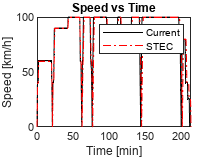

% Plotting

figure(1)
plot((1/60)*cumsum([0,time_curve(1:end-1)]),(18/5)*velocity_curve,'k-')
hold on
plot((1/60)*STEC_Time,STEC_Speed,'r-.')
hold off
title("Speed vs Time")
xlabel("Time [min]")
ylabel("Speed [km/h]")
legend('Current','STEC')
xlswritefig(gcf,'Results3.xlsx','Sheet1','L2')

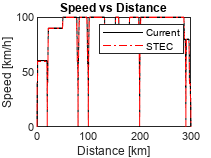


figure(2)
plot((1/1000)*cumsum(distance_curve),(18/5)*velocity_curve,'k-')
hold on
plot(STEC_distance,STEC_Speed,'r-.')
hold off
title("Speed vs Distance")
xlabel("Distance [km]")
ylabel("Speed [km/h]")
legend('Current','STEC')
xlswritefig(gcf,'Results3.xlsx','Sheet1','U2')

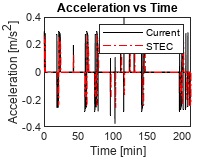


figure(3)
plot((1/60)*cumsum(time_curve),acc_curve,'k-')
hold on
plot((1/60)*STEC_Time,STEC_Acc,'r-.')
hold off
title("Acceleration vs Time")
xlabel("Time [min]")
ylabel("Acceleration [m/s^2]")
legend('Current','STEC')
xlswritefig(gcf,'Results3.xlsx','Sheet1','L26')

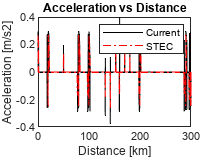


figure(4)
plot((1/1000)*cumsum(distance_curve),acc_curve,'k-')
hold on
plot(STEC_distance,STEC_Acc,'r-.')
hold off
title("Acceleration vs Distance")
xlabel("Distance [km]")
ylabel("Acceleration [m/s2]")
legend('Current','STEC')
xlswritefig(gcf,'Results3.xlsx','Sheet1','U26')

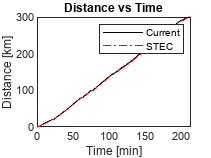


figure(5)
plot((1/60)*cumsum(time_curve),0.001*cumsum(distance_curve),'k-')
hold on
plot((1/60)*STEC_Time,STEC_distance,'r-.')
hold off
title("Distance vs Time")
xlabel("Time [min]")
ylabel("Distance [km]")
legend('Current','STEC')
xlswritefig(gcf,'Results3.xlsx','Sheet1','L48')

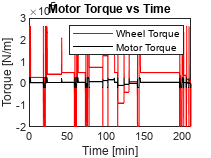


figure(6)
plot((1/60)*cumsum(time_curve),wheelTorque_curve,'r')
hold on
plot((1/60)*cumsum(time_curve),motorTorque_curve,'k')
hold off
title("Motor Torque vs Time")
xlabel("Time [min]")
ylabel("Torque [N/m]")
legend('Wheel Torque','Motor Torque')
xlswritefig(gcf,'Results3.xlsx','Sheet1','U48')

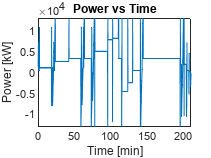


figure(7)
plot((1/60)*cumsum(time_curve),0.001*motorPower_curve)
title("Power vs Time")
xlabel("Time [min]")
ylabel("Power [kW]")
xlswritefig(gcf,'Results3.xlsx','Sheet1','L70')

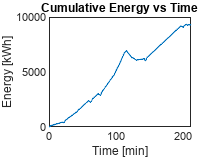


figure(8)
plot((1/60)*cumsum(time_curve),0.001*motorEnergy_curve/3600)
title("Cumulative Energy vs Time")
xlabel("Time [min]")
ylabel("Energy [kWh]")
xlswritefig(gcf,'Results3.xlsx','Sheet1','U70')

% V = [100 90 75 100 75 90 100 100 78 100 99 98 100 99 100 66 77]
% d = [30 10 10 8 10 10 18 7 6 3 2 1 1.5 12 14 16 18]

% [sortedd,rank_d] = sort(d,"ascend") % min to max distances
%
% correspondingV = V(rank_d)
%
% [~,indicesOfV] = maxk(correspondingV,3)
%
% xx = rank_d(indicesOfV)
% d([13,10,8])
% V(xx)



function [pLocal2Global,truncated] = function_speed_reduction(ranking_criterion,z,stations,p,max_speed,section_distance,max_speed_track)

truncate = 1;

if ranking_criterion == 1 % maximum(p(i)*speed(i)*section_distance(i)) and Not considering the last section in which braking occurs

    pLocal = p(stations(z) : stations(z+1) - truncate);

    [~,ranking] = sort(pLocal(1:end)'.*max_speed_track(stations(z):stations(z+1) - truncate).*section_distance(stations(z) : stations(z+1) - truncate)); % Ranking criterion of V_max*section length % pLocal(1:end-1) check if its fine

    [~,idx_maxRanking] = max(ranking); % to decide maximum or minimum

    pLocal(idx_maxRanking) = pLocal(idx_maxRanking) - 0.01;


elseif ranking_criterion == 2 % Peak shaving i.e. Min distance, Max Velocity

    truncate = 1*((stations(z+1) - stations(z)) > 2); % only one break point between two consecutive stations

    pLocal = p(stations(z) + truncate : stations(z+1) - 1 - truncate);
    %p(stations(z) + (ranking_criterion - 1 - 1*((stations(z+1) - stations(z)) < 2)) : stations(z+1) - ranking_criterion + 1*((stations(z+1) - stations(z)) < 2)) = outputA;
    [~,rank_d] = sort(section_distance(stations(z) + truncate : stations(z+1) - 1 - truncate),"ascend"); % min to max distances

    %V = pLocal'.*max_speed_track(stations(z) + truncate : stations(z+1) - 1 - truncate);
    V = max_speed_track(stations(z) + truncate : stations(z+1) - 1 - truncate);
    correspondingV = V(rank_d);

    [~,maxVlocation] = maxk(correspondingV,length(rank_d));

    indicesOfV = rank_d(maxVlocation);

    if and(pLocal(indicesOfV(1))*max_speed(stations(z) + indicesOfV(1)) >...
            p(stations(z) + indicesOfV(1) - 1)*max_speed(stations(z) + indicesOfV(1) - 1),...
            pLocal(indicesOfV(1)) > 0.5)     % pLocal(indicesOfV(1) - 1)*max_speed(indicesOfV(1))

        pLocal(indicesOfV(1)) = pLocal(indicesOfV(1)) - 0.01;

    elseif and(pLocal(indicesOfV(2))*max_speed(stations(z) + indicesOfV(2)) >...
            p(stations(z) + indicesOfV(2) - 1)*max_speed(stations(z) + indicesOfV(2) - 1),...
            pLocal(indicesOfV(2)) > 0.5)

        pLocal(indicesOfV(2)) = pLocal(indicesOfV(2)) - 0.01;

    elseif and(pLocal(indicesOfV(3))*max_speed(stations(z) + indicesOfV(3)) >...
            p(stations(z) + indicesOfV(3) - 1)*max_speed(stations(z) + indicesOfV(3) - 1),...
            pLocal(indicesOfV(3)) > 0.5)

        pLocal(indicesOfV(3)) = pLocal(indicesOfV(3)) - 0.01;

    elseif and(pLocal(indicesOfV(4))*max_speed(stations(z) + indicesOfV(4)) >...
            p(stations(z) + indicesOfV(4) - 1)*max_speed(stations(z) + indicesOfV(4) - 1),...
            pLocal(indicesOfV(4)) > 0.5)

        pLocal(indicesOfV(4)) = pLocal(indicesOfV(4)) - 0.01;

    elseif and(pLocal(indicesOfV(5))*max_speed(stations(z) + indicesOfV(5)) >...
            p(stations(z) + indicesOfV(5) - 1)*max_speed(stations(z) + indicesOfV(5) - 1),...
            pLocal(indicesOfV(5)) > 0.5)

        pLocal(indicesOfV(5)) = pLocal(indicesOfV(5)) - 0.01;

    elseif pLocal(indicesOfV(2))*max_speed(stations(z) + truncate + indicesOfV(2)) >...
            p(stations(z) + truncate + indicesOfV(2) - 1)*max_speed(stations(z) + indicesOfV(2) - 1)


        pLocal(indicesOfV(2)) = pLocal(indicesOfV(2)) - 0.01;

    else

        warning('Train arriving faster')

    end


elseif ranking_criterion == 3

    pLocal = p(stations(z) : stations(z+1) - truncate);

    pLocal = pLocal - 0.01;


elseif ranking_criterion == 4

    pLocal = p(stations(z) : stations(z+1) - truncate);

    %[~,ranking] = sort(max_speed_track(stations(z):stations(z+1) - truncate)); % Ranking criterion of V_max*section length % pLocal(1:end-1) check if its fine

    [~,idx_maxRanking] = sort(max_speed_track(stations(z):stations(z+1) - truncate),'descend'); % to decide maximum or minimum

    terminating = 0;

    i = 1;

    while i <= length(pLocal)

        %     if and(pLocal(idx_maxRanking(1))*max_speed(stations(z) + idx_maxRanking(1) - 1) >=...
        %             p(stations(z) + idx_maxRanking(1) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(1) - 1 - 1),...
        %             pLocal(idx_maxRanking(1)) > 0.5)

        if and(pLocal(idx_maxRanking(i))*max_speed(stations(z) + idx_maxRanking(i) - 1) >=...
                p(stations(z) + idx_maxRanking(i) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(i) - 1 - 1),...
                pLocal(idx_maxRanking(i)) > 0.5)

            pLocal(idx_maxRanking(i)) = pLocal(idx_maxRanking(i)) - 0.01;

            break;

        elseif i < length(pLocal)

            i = i + 1;

        else

            i = 1;

            while i <= length(pLocal)

                if pLocal(idx_maxRanking(i)) > 0.5

                    pLocal(idx_maxRanking(i)) = pLocal(idx_maxRanking(i)) - 0.01;

                    terminating = 1;

                    break;

                end

                i = i + 1;
            end

        end

        if terminating > 0

            break;

        end

    end
    %     if and(pLocal(idx_maxRanking(1))*max_speed(stations(z) + idx_maxRanking(1) - 1) >=...
    %             p(stations(z) + idx_maxRanking(1) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(1) - 1 - 1),...
    %             pLocal(idx_maxRanking(1)) > 0.5)     % pLocal(indicesOfV(1) - 1)*max_speed(indicesOfV(1))
    %
    %         pLocal(idx_maxRanking(1)) = pLocal(idx_maxRanking(1)) - 0.01;
    %
    %     elseif and(pLocal(idx_maxRanking(2))*max_speed(stations(z) + idx_maxRanking(2) - 1) >=...
    %             p(stations(z) + idx_maxRanking(2) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(2) - 1 - 1),...
    %             pLocal(idx_maxRanking(2)) > 0.5)
    %
    %         pLocal(idx_maxRanking(2)) = pLocal(idx_maxRanking(2)) - 0.01;
    %
    %     elseif and(pLocal(idx_maxRanking(3))*max_speed(stations(z) + idx_maxRanking(3) - 1) >=...
    %             p(stations(z) + idx_maxRanking(3) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(3) - 1 - 1),...
    %             pLocal(idx_maxRanking(3)) > 0.5)
    %
    %         pLocal(idx_maxRanking(3)) = pLocal(idx_maxRanking(3)) - 0.01;
    %
    %     elseif and(pLocal(idx_maxRanking(4))*max_speed(stations(z) + idx_maxRanking(4) - 1) >=...
    %             p(stations(z) + idx_maxRanking(4) - 1 - 1)*max_speed(stations(z) + idx_maxRanking(4) - 1 - 1),...
    %             pLocal(idx_maxRanking(4)) > 0.5)
    %
    %         pLocal(idx_maxRanking(4)) = pLocal(idx_maxRanking(4)) - 0.01;
    %
    %     end

elseif ranking_criterion == 5

    pLocal = p(stations(z) : stations(z+1) - truncate);

    %[~,ranking] = sort(max_speed_track(stations(z):stations(z+1) - truncate)); % Ranking criterion of V_max*section length % pLocal(1:end-1) check if its fine

    %[V,idx_maxRanking] = sort(max_speed_track(stations(z):stations(z+1) - truncate),'descend'); % to decide maximum or minimum

    [V,idx_maxRanking] = sort(pLocal'.*max_speed_track(stations(z):stations(z+1) - truncate),'descend'); % to decide maximum or minimum

    noOfEqualV = find(abs(V - V(1)) < 0.1); % 0.1 can be changed also to a bigger or smaller number

    noOfEqualV = noOfEqualV(end);

    maxVequalIdx = idx_maxRanking(1:noOfEqualV);

    pLocal(maxVequalIdx) = pLocal(maxVequalIdx) - 0.001;

end

pLocal2Global = pLocal;

truncated = truncate;

end



function [vCoast_field,coasting_count,a_x_field] = f_coast(dx,equi_mass,A,B,C,v_in,grad,curve,v_lim)

v_out = v_in;

coasting_count = 0;

vCoast_field = v_in;

a_x_field = 0;

while v_out > v_lim

    a_x = -(A + B*v_in + C*v_in^2 + grad + curve)/equi_mass;

    if a_x > 0
        error('Positive acceleration = %f m/s2 is detected which does not allow coasting to take place as it accelerates the train instead of braking it. It might be due to downhill section',a_x)
    end

    if (v_in^2 + 2*dx*a_x) > 0
        v_out = sqrt(v_in^2 + 2*dx*a_x);

    else

        v_out = 0;

    end

    vCoast_field = [vCoast_field,v_out];

    a_x_field = [a_x_field,a_x];

    coasting_count = coasting_count + 1;

    v_in = v_out;

end

end

function xlswritefig(hFig,filename,sheetname,xlcell)
% XLSWRITEFIG  Write a MATLAB figure to an Excel spreadsheet
%
% xlswritefig(hFig,filename,sheetname,xlcell)
%
% All inputs are optional:
%
%    hFig:      Handle to MATLAB figure.  If empty, current figure is
%                   exported
%    filename   (string) Name of Excel file, including extension.  If not specified, contents will
%                  be opened in a new Excel spreadsheet.
%    sheetname:  Name of sheet to write data to. The default is 'Sheet1'
%                       If specified, a sheet with the specified name must
%                       exist
%    xlcell:     Designation of cell to indicate the upper-left corner of
%                  the figure (e.g. 'D2').  Default = 'A1'
%
% Requirements: Must have Microsoft Excel installed.  Microsoft Windows
% only.
%
% Ex:
% Paste the current figure into a new Excel spreadsheet which is left open.
%         plot(rand(10,1))
%         drawnow    % Maybe overkill, but ensures plot is drawn first
%         xlswritefig
%
% Specify all options.
%         hFig = figure;
%         surf(peaks)
%         xlswritefig(hFig,'MyNewFile.xlsx','Sheet2','D4')
%         winopen('MyNewFile.xlsx')
% Taken from Mathworks this function for excel plotting
% The MathWorks

if nargin==0 || isempty(hFig)
    hFig = gcf;
end
if nargin<2 || isempty(filename)
    filename ='';
    dontsave = true;
else
    dontsave = false;

    % Create full file name with path
    filename = fullfilename(filename);
end
if nargin < 3 || isempty(sheetname)
    sheetname = 'Sheet1';
end
if nargin<4
    xlcell = 'A1';
end
% Put figure in clipboard
if ~verLessThan('matlab','9.8')
    copygraphics(hFig)
else
    % For older releases, use hgexport. Set renderer to painters to make
    % sure it looks right.
    r = get(hFig,'Renderer');
    set(hFig,'Renderer','Painters')
    drawnow
    hgexport(hFig,'-clipboard')
    set(hFig,'Renderer',r)
end
% Open Excel, add workbook, change active worksheet,
% get/put array, save.
% First, open an Excel Server.
Excel = actxserver('Excel.Application');
% Two cases:
% * Open a new workbook, save with given file name
% * Open an existing workbook
if exist(filename,'file')==0
    % The following case if file does not exist (Creating New File)
    op = invoke(Excel.Workbooks,'Add');
    %     invoke(op, 'SaveAs', [pwd filesep filename]);
    new=1;
else
    % The following case if file does exist (Opening File)
    %     disp(['Opening Excel File ...(' filename ')']);
    op = invoke(Excel.Workbooks, 'open', filename);
    new=0;
end
% set(Excel, 'Visible', 0);
% Make the specified sheet active.
try
    Sheets = Excel.ActiveWorkBook.Sheets;
    target_sheet = get(Sheets, 'Item', sheetname);
catch %#ok<CTCH>   Suppress so that this function works in releases without MException
    % Add the sheet if it doesn't exist
    target_sheet = Excel.ActiveWorkBook.Worksheets.Add();
    target_sheet.Name = sheetname;
end
invoke(target_sheet, 'Activate');
Activesheet = Excel.Activesheet;
% Paste to specified cell
Paste(Activesheet,get(Activesheet,'Range',xlcell,xlcell))
% Save and clean up
if new && ~dontsave
    invoke(op, 'SaveAs', filename);
elseif ~new
    invoke(op, 'Save');
else  % New, but don't save
    set(Excel, 'Visible', 1);
    return  % Bail out before quitting Excel
end
invoke(Excel, 'Quit');
delete(Excel)
end
function filename = fullfilename(filename)
[filepath, filename, fileext] = fileparts(filename);
if isempty(filepath)
    filepath = pwd;
end
if isempty(fileext)
    fileext = '.xlsx';
end
filename = fullfile(filepath, [filename fileext]);
end
